T=1200:-0.01:1100

T = 	1.0e+03 *

    1.2000    1.2000    1.2000    1.2000    1.2000    1.2000    1.1999    1.1999    1.1999    1.1999    1.1999    1.1999    1.1999    1.1999    1.1999    1.1998    1.1998    1.1998    1.1998    1.1998    1.1998    1.1998    1.1998    1.1998    1.1998    1.1998    1.1997    1.1997    1.1997    1.1997    1.1997    1.1997    1.1997    1.1997    1.1997    1.1997    1.1996    1.1996    1.1996    1.1996    1.1996    1.1996    1.1996    1.1996    1.1996    1.1995    1.1995    1.1995    1.1995    1.1995


%R0=0.01117;
R0=-10;
T=T.^2;
Alp=(exp(0.001*(8.85*(10e5./(T))+0.99)));
f=1:-0.0001:0;
%w=((8.85*(10e5./(T)))+0.99);


for i=1:length(f)
    R(i)=(R0+1000)*(f(i)^(Alp(i)-1))-1000;
end
R1=((R+1000).*Alp)-1000

R1 = 	1.0e+03 *

   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029


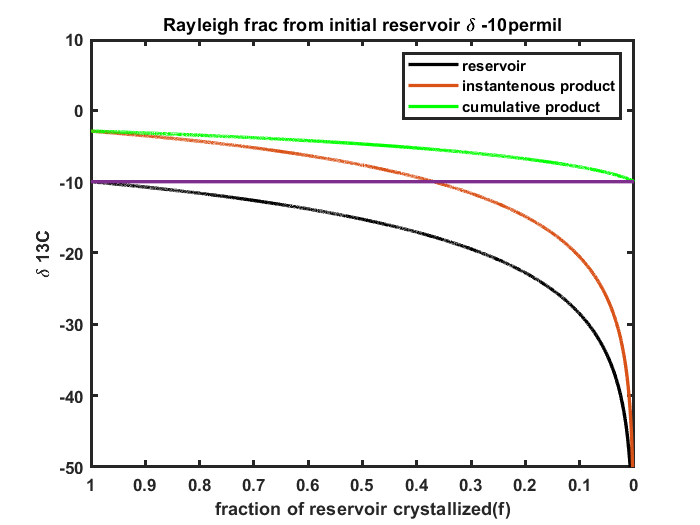

plot(f,R,'k',"LineWidth",2)
 hold on
% D1=D+((Alp-1).*log(f));
plot(f,R1,"LineWidth",2)
set(gca, 'XDir','reverse')
ylim([-50 10])
R2=((R0+1000).*((1-(f.^(Alp)))./(1-f)))-1000;
plot(f,R2,"g","LineWidth",2)
plot([f(1) f(end)],[R0 R0],"LineWidth",2)
h=gca;
%legend;
% legendCell = cellstr(num2str(step1', '%2.3f days'));
% legend(legendCell);
title("Rayleigh frac from initial reservoir \delta -10permil")
h.YLimMode='manual';
h.FontSize=10;
h.FontWeight="bold";
h.LineWidth=1.8;
xlabel('fraction of reservoir crystallized(f)');
ylabel('\delta 13C');
legend("reservoir","instantenous product","cumulative product")
%print(gcf,'rayleigh1.png','-dpng','-r330');
hold off
hold off

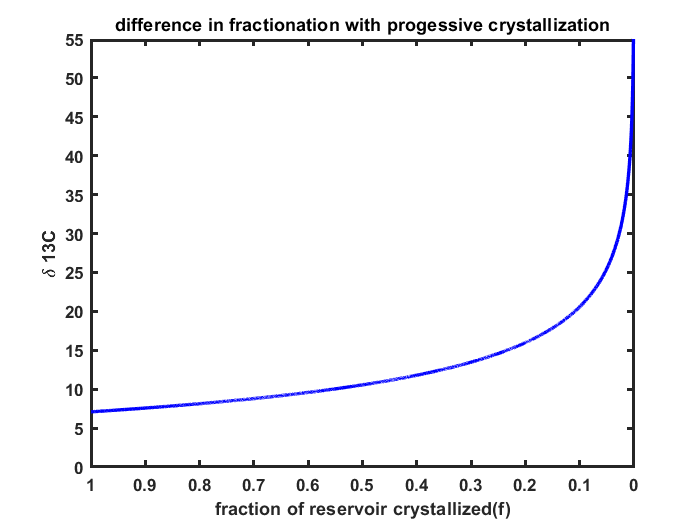


Ch=abs(R2-R);
plot(f,Ch,'b',"LineWidth",2)
ylim([0 55])
set(gca, 'XDir','reverse')
h=gca;
%legend;
% legendCell = cellstr(num2str(step1', '%2.3f days'));
% legend(legendCell);
title("difference in fractionation with progessive crystallization")
h.YLimMode='manual';
h.FontSize=10;
h.FontWeight="bold";
h.LineWidth=1.8;
xlabel('fraction of reservoir crystallized(f)');
ylabel('\delta 13C');

print(gcf,'rayleigh2.png','-dpng','-r330');
hold off
hold off